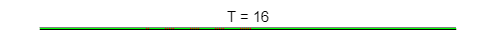

axes;%建立坐标轴
set(gcf,'DoubleBuffer','on');   
%设置的目的是为了防止在不断循环画动画的时候会产生闪烁的现象
S=zeros(2,1000);%初始化S矩阵
for i=1:5:254
    for j=1:2
        S(j,i)=1;
    end
end
%将车的位置标记在S上
Sk=zeros(6,1000);%初始化整个马路的矩阵Sk
Sk(3:4,1:1000)=S;%将车道加入整个马路
C=zeros(6,1000,3);%构造一个302*302*3的张量（数组）
R=zeros(6,1000);%初始化R矩阵
G=zeros(6,1000); %初始化G矩阵
for i=1:1000
    if Sk(3,i)==1
        R(3:4,i)=1;
    else
        G(3:4,i)=1;
    end
end
%分别在R，G上标记出车辆和没有车辆的位置
C(1:6,1:1000,1)=R;%将C的第一层赋值为R矩阵
C(1:6,1:1000,2)=G;%将C的第二层赋值为G矩阵
Ci=imshow(C);%在图窗中显示灰度图像 I
ti=0;%初始化时间
tp=title(['T = ',num2str(ti)]);%在标题处显示时间
mm=0;%初始化mm
while 1
    ti=ti+1;%时间的递增
    mm=0;%初始化mm
    Sk=zeros(6,1000);%初始化Sk
    for i=1:5:251
        Sk(3:4,i+ti^2)=1;
        if i+ti^2>251
            mm=mm+1;
        end
    end
   %根据模型假设，加速度为2，且车辆可以一直作加速运动
   %采用最简单的运动学公式，用初位置+行驶距离=末位置
    R=zeros(6,1000);%初始化R
    G=zeros(6,1000);%初始化G
    for i=1:1000
    if Sk(3,i)==1
        R(3:4,i)=1;
    else
        G(3:4,i)=1;
    end
    end
    %将车辆的位置更新于R、G矩阵中
    C(:,:,1)=R;%把C的第一层赋值为R
    C(:,:,2)=G;%把C的第二层赋值为G
    set(Ci,'CData',C);%第一行是显示图像，C是图像的矩阵，Ci上面有定义，是显示图像。
    set(tp,'string',['T = ',num2str(ti)]); %第二行是设置图像的标题，显示T=当前时刻
    pause(0.2);
    if mm>50
        break;
    end
    %在车辆全部通过红路灯时跳出循环
end

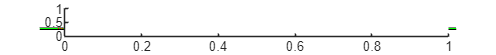

axes;%建立坐标轴

set(gcf,'DoubleBuffer','on');   
%设置的目的是为了防止在不断循环画动画的时候会产生闪烁的现象
S=zeros(2,1000);%初始化S矩阵
for i=1:5:254
    for j=1:2
        S(j,i)=1;
    end
end
%将车的位置标记在S上
Sk=zeros(6,1000);%初始化整个马路的矩阵Sk
Sk(3:4,1:1000)=S;%将车道加入整个马路
C=zeros(6,1000,3);%构造一个302*302*3的张量（数组）
R=zeros(6,1000); %初始化R矩阵
G=zeros(6,1000); %初始化G矩阵
for i=1:1000
    if Sk(3,i)==1
        R(3:4,i)=1;
    else
        G(3:4,i)=1;
    end
end
%分别在R，G上标记出车辆和没有车辆的位置
C(1:6,1:1000,1)=R;%将C的第一层赋值为R矩阵
C(1:6,1:1000,2)=G;%将C的第二层赋值为G矩阵
Ci=imshow(C);%在图窗中显示灰度图像 I
ti=0;%初始化时间
tp=title(['T = ',num2str(ti)]);%在标题处显示时间
mm=0;%初始化mm
while 1
    ti=ti+1;%时间的递增
    mm=0;%初始化mm
    Sk=zeros(6,1000);%初始化Sk
    for i=1:5:251
        Sk(3:4,i+ti^2)=1;
        for i=1:5:250
        if ti<=5
        Sk(3:4,i+ti^2)=1;
        if i+ti^2>251
            mm=mm+1;
        end
        else
            Sk(3:4,i+25+10*(ti-5))=1;
            if i+25+10*(ti-5)>251
                mm=mm+1;
            end
        end
        end
    end
   %根据模型假设，加速度为2，但是有最大限速10，所以分两个情况讨论
   %在加速时期通过红绿灯和在匀速时期通过红绿灯
   %采用最简单的运动学公式，用初位置+行驶距离=末位置
    R=zeros(6,1000);%初始化R
    G=zeros(6,1000);%初始化G
    for i=1:1000
    if Sk(3,i)==1
        R(3:4,i)=1;
    else
        G(3:4,i)=1;
    end
    end
    %将车辆的位置更新于R、G矩阵中
    C(:,:,1)=R;%把C的第一层赋值为R
    C(:,:,2)=G;%把C的第二层赋值为G
    set(Ci,'CData',C);%第一行是显示图像，C是图像的矩阵，Ci上面有定义，是显示图像。
    set(tp,'string',['T = ',num2str(ti)]); %第二行是设置图像的标题，显示T=当前时刻
    pause(0.2);
    if mm>50
        break;
    end
    %在车辆全部通过红路灯时跳出循环
end
axes;%建立坐标轴

set(gcf,'DoubleBuffer','on');   
%设置的目的是为了防止在不断循环画动画的时候会产生闪烁的现象
S=zeros(2,1000);%初始化S矩阵
for i=1:5:254
    for j=1:2
        S(j,i)=1;
    end
end
%将车的位置标记在S上
Sk=zeros(6,1000);%初始化整个马路的矩阵Sk
Sk(3:4,1:1000)=S;%将车道加入整个马路
C=zeros(6,1000,3);%构造一个302*302*3的张量（数组）
R=zeros(6,1000);%初始化R矩阵
G=zeros(6,1000); %初始化G矩阵
for i=1:1000
    if Sk(3,i)==1
        R(3:4,i)=1;
    else
        G(3:4,i)=1;
    end
end
%分别在R，G上标记出车辆和没有车辆的位置
C(1:6,1:1000,1)=R;%将C的第一层赋值为R矩阵
C(1:6,1:1000,2)=G;%将C的第二层赋值为G矩阵
Ci=imshow(C);%在图窗中显示灰度图像 I
ti=0;%初始化时间
tp=title(['T = ',num2str(ti)]);%在标题处显示时间
mm=0;%初始化mm
while 1
    ti=ti+1;%时间的递增
    mm=0;%初始化mm
    Sk=zeros(6,1000);%初始化Sk
    for i=1:5:251
        Sk(3:4,i+ti^2)=1;
        if i+ti^2>251
            mm=mm+1;
        end
    end
   %根据模型假设，加速度为2，且车辆可以一直作加速运动
   %采用最简单的运动学公式，用初位置+行驶距离=末位置
    R=zeros(6,1000);%初始化R
    G=zeros(6,1000);%初始化G
    for i=1:1000
    if Sk(3,i)==1
        R(3:4,i)=1;
    else
        G(3:4,i)=1;
    end
    end
    %将车辆的位置更新于R、G矩阵中
    C(:,:,1)=R;%把C的第一层赋值为R
    C(:,:,2)=G;%把C的第二层赋值为G
    set(Ci,'CData',C);%第一行是显示图像，C是图像的矩阵，Ci上面有定义，是显示图像。
    set(tp,'string',['T = ',num2str(ti)]); %第二行是设置图像的标题，显示T=当前时刻
    pause(0.2);
    if mm>50
        break;
    end
    %在车辆全部通过红路灯时跳出循环
end